syms f x a b c d fn fb ftan xlim

f = x^(1/4) * exp(-b*x^2) 

$$f = x^{1/4}\,{\mathrm{e}}^{-b\,x^{2}}$$


df = diff(f,x);
criticalPoints = solve(df == 0, x)

$$criticalPoints = \left(\begin{array}{c} -\frac{\sqrt{2}}{4\,\sqrt{b}}\\ \frac{\sqrt{2}}{4\,\sqrt{b}} \end{array}\right)$$

maxPoint = criticalPoints(2);
maxVal = subs(f, x, maxPoint)

$$maxVal = {\mathrm{e}}^{-\frac{1}{8}}\,{\left(\frac{\sqrt{2}}{4\,\sqrt{b}}\right)}^{1/4}$$


fb = c  % bias function

$$fb = c$$

fn = a * 1/(1+c) * (f / maxVal + fb)  % normalized + biased function

$$fn = \frac{a\,\left(c+\frac{x^{1/4}\,{\mathrm{e}}^{1/8}\,{\mathrm{e}}^{-b\,x^{2}}}{{\left(\frac{\sqrt{2}}{4\,\sqrt{b}}\right)}^{1/4}}\right)}{c+1}$$


% % check consistency
% dfn = diff(fn,x)
% criticalPointsn = solve(dfn == 0, x)
% maxPointn = criticalPointsn(2);
% maxValn = subs(fn, x, maxPointn)

ftan = d * tan(x * pi / 2 / xlim)  % smooth saturation

$$ftan = d\,\tan\left(\frac{\pi \,x}{2\,\mathrm{xlim}}\right)$$

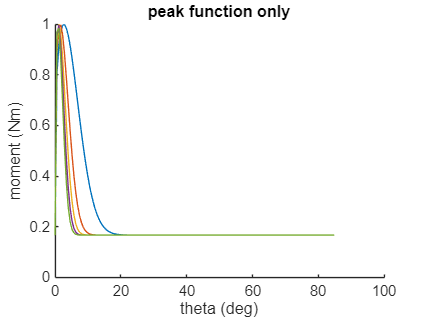

xlim = 85/180*pi;

figure()
hold on
x = 0:0.01:xlim;

for i = 1:2:10
    a = 1;
    b = i * 180/pi;
    c = 0.2; % 0
    plot(x*180/pi,double(subs(fn)))
end
title("peak function only")
xlabel("theta (deg)")
ylabel("moment (Nm)")

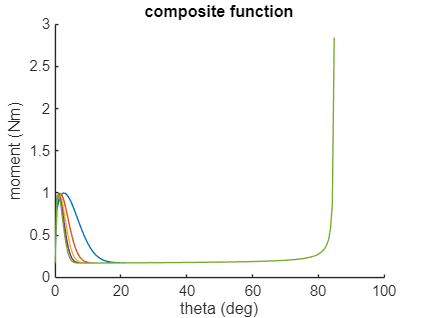


figure()
hold on
for i = 1:2:10
    a = 1;
    b = i * 180/pi;
    d = .01 * a; % keep fixed
    plot(x*180/pi,double(subs(fn + ftan)))
end
title("composite function")
xlabel("theta (deg)")
ylabel("moment (Nm)")